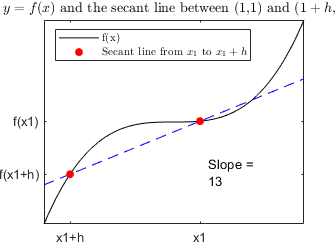

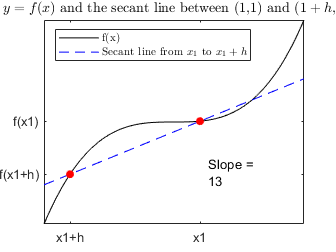

% syms x
% f = symfun(3*x+1,x);
% g = symfun(2*x^2-x+2,x);
% pt = 3;
% h = 0.05;
%     animateProductRule(f,g,pt,h,["#4DBEEE","#A2142F","#77AC30"]) %#ok<*UNRCH> 


syms x
f(x) = x^3;
x1 = 1;
fx1 = f(x1);
fplot(f(x), "k")
hold on
scatter(x1,f(x1),"r","Filled")
rocker1 = -4:.1:3;
rocker2 = 3:-.1:-4;
idx1 = find(rocker1 == 1);
idx2 = find(rocker2 == 1);
rocker1 = [rocker1(1:idx1-1) rocker1(idx1+1:end)];
rocker2 = [rocker2(1:idx2-1) rocker2(idx2+1:end)];
for x2 = [rocker1 rocker2]
graphSecant(@(x) f(x),x1,x2,"f");
if x1 == x2
   pause(10)
else
pause(0)
end
end

function [fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h)
syms x
fx = double(f(pt));
fxph = double(f(pt+h));
gx = double(g(pt));
gxph = double(g(pt+h));
end

function [zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax)
xlimits = ax.XLim;
ylimits = ax.YLim;
axInnerPosition = ax.InnerPosition;
yScale = axInnerPosition(4);
xScale = axInnerPosition(3);
x0 = axInnerPosition(1);
y0 = axInnerPosition(2);
xMin = xlimits(1);
xMax = xlimits(2);
yMin = ylimits(1);
yMax = ylimits(2);
zxs = -xMin/(xMax-xMin)*xScale+x0;
zys = -yMin/(yMax-yMin)*yScale+y0;
fxs = (fx-xMin)/(xMax-xMin)*xScale+x0;
gxs = (gx-yMin)/(yMax-yMin)*yScale+y0;
fxphs = (fxph-xMin)/(xMax-xMin)*xScale+x0;
gxphs = (gxph-yMin)/(yMax-yMin)*yScale+y0;
end

function fig = showProductRule(f, g, pt, h, cols)
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
scatter([0 fx fx 0], [0 0 gx gx],"white")
[xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(1),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(3),"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx);
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",cols(2),"EdgeColor","k")
title("Product Rule")
xlabel("$f(x)$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
fig = gcf;
end

function mpt = findMidPt(opt1,opt2)
mpt = min([opt1 opt2])+.5*abs(opt2-opt1);
end

function [xpt,ypt] = findMidCoords(xopt1,xopt2,yopt1,yopt2,xshift,yshift)
if xshift < 0
    xpt = max([findMidPt(xopt1,xopt2)+xshift min([xopt1 xopt2])]);
else
    xpt = max([min([findMidPt(xopt1,xopt2)+xshift max([xopt1 xopt2])-.1]) 0]);
end
if yshift < 0
    ypt = max([findMidPt(yopt1,yopt2)+yshift min([yopt1 yopt2])]);
else
    ypt = max([min([findMidPt(yopt1,yopt2)+yshift max([yopt1 yopt2])-.1]) 0]);
end
end

function [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h)
ax = gca;
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
[zxs,zys,fxs,~,gxs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
[xpt,ypt] = findMidCoords(zxs,fxs,zys,gxs,-.1,-.1);
end

function [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h)
ax = gca;
[fx,fxph,gx,gxph] = calcPointVals(f,g,pt,h);
[zxs,zys,fxs,fxphs,gxs,gxphs] = calcScaledPointVals(fx,fxph,gx,gxph,ax);
if abs(fxphs-zxs)>abs(fxs-zxs)
    fLxs = fxs;
    fFxs = fxphs;
else
    fLxs = fxphs;
    fFxs = fxs;
end
if abs(gxphs-zys)>abs(gxs-zys)
    gLxs = gxs;
    gFxs = gxphs;
else
    gLxs = gxphs;
    gFxs = gxs;
end
end

function annProdfg(f,g,pt,h,choice)
[xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
if choice
    dim = [findMidPt(xpt,zxs) findMidPt(ypt,zys) .216 .05];
else
    dim = [xpt ypt .216 .05];
end
annotation("textbox",dim,"String","Area = $f(x)\cdot g(x)$","Interpreter","latex")
end

function annProddfdg(f,g,pt,h,col2)
[xpt,ypt] = setMidPts(f,g,pt,h);
[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
annotation("textarrow",[xUpt fLxs],[yUpt gLxs],"String","$\Delta f \cdot \Delta g$","TextEdgeColor",col2,"Color",col2,"Interpreter","latex")
end

function annProdChange(f,g,pt,h,col3)
[xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
if fLxs > xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = xpt;
elseif fLxs < xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = findMidPt(xpt,zxs);
elseif fLxs > xpt && gLxs < ypt
    yNpt = findMidPt(ypt,zys);
    xNpt = xpt;
else
    yNpt = findMidPt(ypt,zys);
    xNpt = findMidPt(xpt,zxs);
end
annotation("textarrow",[xUpt fLxs],[yNpt yNpt],"String","$\Delta f \cdot g(x)$","TextEdgeColor",col3,"Interpreter","latex")
annotation("textarrow",[xNpt xNpt],[yUpt gLxs],"String","$f(x) \cdot \Delta g$","TextEdgeColor",col3,"Interpreter","latex")
end

function animateProductRule(f,g,pt,h,cols) %#ok<DEFNU> 
fig = showProductRule(f,g,pt,h,cols)
M(1) = getframe(fig);
col1 = cols(1);
col2 = cols(2);
col3 = cols(3);
fig = showProductRule(f,g,pt,h,[col1 "none" "none"])
annProdfg(f,g,pt,h,0)
M(2) = getframe(fig);
fig = showProductRule(f,g,pt,h,["none" col2 "none"])
annProddfdg(f,g,pt,h,col2)
M(3) = getframe(fig);
fig = showProductRule(f,g,pt,h,["none" "none" col3])
annProdChange(f,g,pt,h,col3)
M(4) = getframe(fig);
fig = showProductRule(f, g, pt, h, cols)
annProdfg(f,g,pt,h,1)
annProddfdg(f,g,pt,h,col2)
annProdChange(f,g,pt,h,col3)
M(5) = getframe(fig);

 for j=1:5
%     for k = 1:180
%     Mall{(j-1)*180+k} = frame2im(M(j));
%     end
Mall{j} = frame2im(M(j))
 end

 filename = "animatedProductRule.gif"; % Specify the output file name
for idx = 1:5
    [A,map] = rgb2ind(Mall{idx},256);
    if idx == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',1);
    else
        imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1);
    end
end
end

function [x0,y0,dx,dy] = findCoords(x0,y0,dx,dy)
if dx < 0
    x0 = double(x0+dx);
    dx = double(abs(dx));
end
if dy < 0
    y0 = double(y0+dy);
    dy = double(abs(dy));
end
end

function out = graphSecant(fh,x1,x2,fstr)
% graphSecant plots a curve y=fh(x) and a secant line between
% two distinct points (x1, fh(x1)) and (x2, fh(x2)) or the tangent
% line to fh(x) at x=x1. It returns a logical value.
%
% graphSecant requires four arguments
%        fh a function handle
%        x1   a number
%        x2   a number
%        fstr a function string, e.g., "f"
% graphSecant returns one value
%        out is a logical that is 1 if x1=x2 and 0 if x1 ~= x2
out = x1==x2;
syms x;
f(x) = fh(x);
if x2 ~= x1
    secant(x) = f(x1) + (f(x2)-f(x1))/(x2-x1)*(x-x1);
else
    df = diff(f);
    secant(x) = f(x1) + df(x1)*(x-x1);
end
fplot(f(x),"k")
hold on
fplot(secant(x),"b--")
scatter(x1,f(x1),"r","Filled")
scatter(x2,f(x2),"r","Filled")
ax = gca;
noTickOverlaps(x1,x2,"x1","x1+h",ax,"x","horiz")
y2 = double(simplify(f(x2)));
y1 = double(simplify(f(x1)));
noTickOverlaps(y1,y2,fstr+"(x1)",fstr+"(x1+h)",ax,"y","vert")
if x1 == x2
    legend([fstr+"(x)","Tangent line at $x_1$"],"Location","northwest","Interpreter","latex")
else
    legend([fstr+"(x)","Secant line from $x_1$ to $x_1+h$"],"Location","northwest","Interpreter","latex")
end
hold off
formatStr = "$y = %s(x)$";
fStringL = compose(formatStr,fstr);
if out
    title("Plot of " + fStringL + " and the tangent line through (" + x1 + "," + double(f(x1)) + ")","Interpreter","latex")
else
    title("Plot of " + fStringL + " and the secant line between (" + x1 + "," + double(f(x1)) + ") and $(1+h,(1+h)^3)$","Interpreter","latex")
end
if x2-x1 ~= 0
m = double((f(x2)-f(x1))/(x2-x1));
else
    m = 3*x1^2;
end
annotation("textbox",[.6 .2 .2 .2],"string","Slope = "+m,"EdgeColor","w")
end

function noTickOverlaps(y1,y2,str1,str2,ax,var,opt)
% y1, y2 are numbers, str1 and str2 are strings that label points y1 and
% y2, ax is a handle to a figure axis, and var is the variable of interest
% and opt is either "vert" or "horiz" to choose how to display overlapping
% labels
switch var
    case "x"
        valMinMax = ax.XLim;
    case "y"
        valMinMax = ax.YLim;
    case "z"
        valMinMax = ax.ZLim;
end

varScale = valMinMax(2)-valMinMax(1);

if y1 == y2
    tickLocations = y1;
    formatStr = "%s = %s";
    labelStr = compose(formatStr,str1,str2);
    tickNames = labelStr;   % This is a label for a single point
elseif 0< y2-y1 && (y2-y1)/varScale < .03
    tickLocations = [y1 y2];
    if opt == "vert"
        tickNames = createStackedLabel(str2,str1);
    elseif opt == "horiz"
        tickNames = [str1+str2 " "];
    end
elseif 0 < y1-y2 && (y1-y2)/varScale < .03
    tickLocations = [y2 y1];
    if opt == "vert"
        tickNames = createStackedLabel(str1,str2);
    elseif opt == "horiz"
        tickNames = [str2+str1 " "];
    end
elseif y1 < y2
    tickLocations = [y1 y2];
    tickNames = [str1 str2];
else
    tickLocations = [y2 y1];
    tickNames = [str2 str1];
end
switch var
    case "x"
        ax.XTick = tickLocations;
        ax.XTickLabel = tickNames;
    case "y"
        ax.YTick = tickLocations;
        ax.YTickLabel = tickNames;
    case "z"
        ax.ZTick = tickLocations;
        ax.ZTickLabel = tickNames;
end
end

function strOut = createStackedLabel(top,bot)
row1 = [" " top];
row2 = [" " bot];
ylabelArray = [row1; row2];
ylabelArray = strjust(pad(ylabelArray,"left"));
strOut = sprintf("%s\\newline%s\n",ylabelArray{:});
end

function exampleFunction(xPosn)
syms y x;
y = 6 + cos(x) - 32/5 * exp(-x/5);
dy = diff(y);
dyVal = subs(dy,x,xPosn);
yVal = subs(y,x,xPosn);
fplot(y)
hold on
xlim([0 25])
scatter(xPosn,yVal,"red","filled")
str = sprintf("$\\lim_{h \\rightarrow 0} \\enspace\\frac{f(%d+h) - f(%d)}{h}$ = %.2f",xPosn,xPosn,dyVal);
annotation("textbox",[.4 .35 .1 .1],"String",str,"FitBoxToText","on","Interpreter","latex");
hold off
title("Compute the definition of the derivative")
end

function checkSlope(slopeGuess,gh,xa,gstr)
% checkSlope determines whether the string slopeGuess matches the actual
% slope of the function defined by the handle gh at the point xa. Then it
% plots the function and the tangent line at x=xa.
%
%     slopeGuess is a string that is "positive", "negative" or "zero"
%     gh is a function handle
%     xa is a number
%     gstr is a string naming the function
syms x;
g(x) = gh(x);
dg = diff(g,x);
slope = double(dg(xa));
if slope > 0
    correctSlope = "positive";
elseif slope < 0
    correctSlope = "negative";
else
    correctSlope = "zero";
end
if (correctSlope == slopeGuess)
    disp("Correct. The slope at x=" + xa + " is " + slopeGuess + ".")
elseif abs(slope)<.1 && abs(slope)>0
    disp("This might be frustrating, but the slope is not identically zero here. In fact, it is " + slope + " which is " + correctSlope + ".")
else
    disp("Incorrect. The slope at x=" + xa + " is " + slope + " which is " + correctSlope + ".")
end
graphSecant(gh,xa,xa,gstr);
end